% 设置中文字体
set(groot, 'DefaultAxesFontName', 'Kaiti');
set(groot, 'DefaultTextFontName', 'Kaiti');
rng(42);  % 设置随机种子

%% ============================================================================
%% 练习一：估算圆周率π
%% Exercise 1: Estimating π using Monte Carlo Method
%% ============================================================================

fprintf("=======================");

fprintf("\n练习一：用蒙特卡洛方法估算圆周率π\n");


练习一：用蒙特卡洛方法估算圆周率π


fprintf("Exercise 1: Estimating π using Monte Carlo Method\n");

Exercise 1: Estimating π using Monte Carlo Method


fprintf("=======================");

fprintf("\n");

%% 1.1 单次估算π值
fprintf("\n1.1 单次估算π值\n");


1.1 单次估算π值



function [pi_estimate, x, y, inside_circle] = estimate_pi_single(n)
    % 使用蒙特卡洛方法估算π值
    % 参数:
    %   n: 随机点的数量
    % 返回:
    %   pi_estimate: π的估计值
    %   x, y: 随机点坐标
    %   inside_circle: 逻辑数组，标记点是否在圆内
    
    % 生成随机点坐标 [-1, 1)
    x = 2 * rand(1, n) - 1;
    y = 2 * rand(1, n) - 1;
    
    % 判断点是否在单位圆内
    inside_circle = (x.^2 + y.^2) <= 1;
    
    % 计算π的估计值
    pi_estimate = 4 * sum(inside_circle) / n;
end

n_points = 10000;
[pi_est, x_coords, y_coords, is_inside] = estimate_pi_single(n_points);

fprintf("使用 %d 个随机点\n", n_points);

使用 10000 个随机点


fprintf("π的估计值: %.6f\n", pi_est);

π的估计值: 3.134800


fprintf("真实π值: %.6f\n", pi);

真实π值: 3.141593


fprintf("绝对误差: %.6f\n", abs(pi_est - pi));

绝对误差: 0.006793


fprintf("相对误差: %.3f%%\n", abs(pi_est - pi)/pi*100);

相对误差: 0.216%


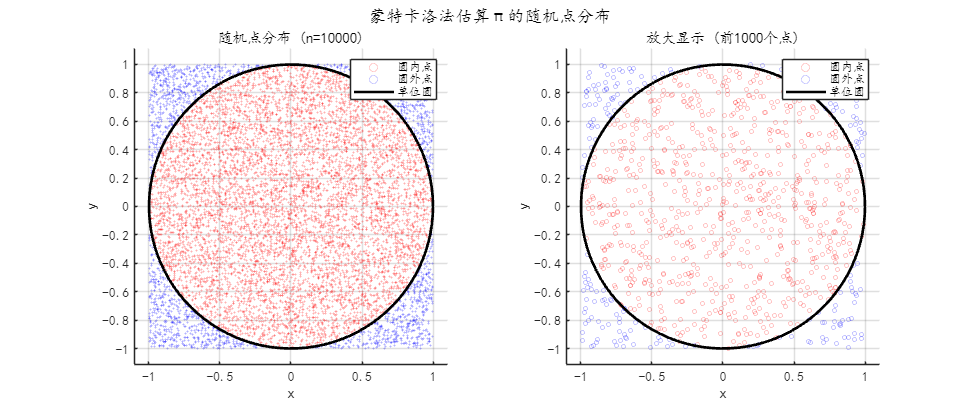


%% 1.2 可视化随机点分布
figure('Position', [100, 100, 1200, 500]);

% 子图1：显示所有点
subplot(1, 2, 1);
scatter(x_coords(is_inside), y_coords(is_inside), 1, 'r', 'MarkerEdgeAlpha', 0.6);
hold on;
scatter(x_coords(~is_inside), y_coords(~is_inside), 1, 'b', 'MarkerEdgeAlpha', 0.6);

% 绘制单位圆
theta = linspace(0, 2*pi, 100);
plot(cos(theta), sin(theta), 'k-', 'LineWidth', 2);

xlim([-1.1, 1.1]);
ylim([-1.1, 1.1]);
axis equal;
grid on;
alpha(0.3);
legend('圆内点', '圆外点', '单位圆');
title(sprintf('随机点分布 (n=%d)', n_points));
xlabel('x');
ylabel('y');

% 子图2：部分放大显示
subplot(1, 2, 2);
n_show = 1000;  % 只显示前1000个点
show_inside = is_inside(1:n_show);
x_sub = x_coords(1:n_show);
y_sub = y_coords(1:n_show);
% 绘制圆内点
scatter(x_sub(show_inside), y_sub(show_inside), 10, 'r', 'MarkerEdgeAlpha', 0.7);
hold on;
% 绘制圆外点
scatter(x_sub(~show_inside), y_sub(~show_inside), 10, 'b', 'MarkerEdgeAlpha', 0.7);
plot(cos(theta), sin(theta), 'k-', 'LineWidth', 2);

xlim([-1.1, 1.1]);
ylim([-1.1, 1.1]);
axis equal;
grid on;
alpha(0.3);
legend('圆内点', '圆外点', '单位圆');
title(sprintf('放大显示 (前%d个点)', n_show));
xlabel('x');
ylabel('y');

sgtitle('蒙特卡洛法估算π的随机点分布');


%% 1.3 收敛性分析
fprintf("\n1.3 收敛性分析\n");


1.3 收敛性分析


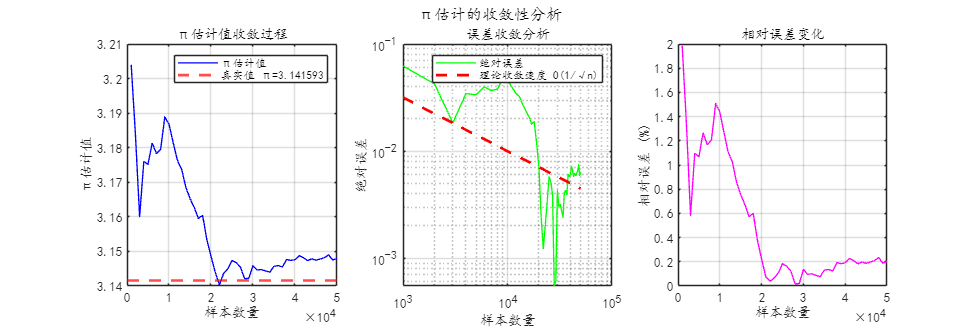


function [n_values, pi_estimates, errors] = analyze_convergence(max_n, step)
    % 分析π估计的收敛过程
    n_values = step:step:max_n;
    pi_estimates = zeros(1, length(n_values));
    errors = zeros(1, length(n_values));
    
    % 生成一次性的大量随机点
    x_all = 2 * rand(1, max_n) - 1;
    y_all = 2 * rand(1, max_n) - 1;
    inside_all = (x_all.^2 + y_all.^2) <= 1;
    
    for i = 1:length(n_values)
        n = n_values(i);
        % 使用前n个点计算π
        pi_est = 4 * sum(inside_all(1:n)) / n;
        pi_estimates(i) = pi_est;
        errors(i) = abs(pi_est - pi);
    end
end

[ n_vals, pi_ests, errs ] = analyze_convergence(50000, 1000);

%% 绘制收敛曲线
figure('Position', [100, 100, 1500, 500]);

% 子图1：π估计值随样本数变化
subplot(1, 3, 1);
plot(n_vals, pi_ests, 'b-', 'LineWidth', 1);
hold on;
yline(pi, 'r--', 'LineWidth', 2);
xlabel('样本数量');
ylabel('π估计值');
title('π估计值收敛过程');
legend('π估计值', sprintf('真实值 π=%.6f', pi));
grid on;
alpha(0.3);

% 子图2：绝对误差随样本数变化
subplot(1, 3, 2);
plot(n_vals, errs, 'g-', 'LineWidth', 1);
hold on;
plot(n_vals, 1./sqrt(n_vals), 'r--', 'LineWidth', 2);
xlabel('样本数量');
ylabel('绝对误差');
title('误差收敛分析');
legend('绝对误差', '理论收敛速度 O(1/√n)');
grid on;
alpha(0.3);
set(gca, 'YScale', 'log');
set(gca, 'XScale', 'log');

% 子图3：相对误差百分比
subplot(1, 3, 3);
relative_errors = errs./pi*100;
plot(n_vals, relative_errors, 'm-', 'LineWidth', 1);
xlabel('样本数量');
ylabel('相对误差 (%)');
title('相对误差变化');
grid on;
alpha(0.3);

sgtitle('π估计的收敛性分析');


% 输出统计信息
fprintf("最终估计值 (n=%d): %.6f\n", n_vals(end), pi_ests(end));

最终估计值 (n=50000): 3.148000


fprintf("最终相对误差: %.3f%%\n", relative_errors(end));

最终相对误差: 0.204%



%% 1.4 多次独立试验的统计分析
fprintf("\n1.4 多次独立试验的统计分析\n");


1.4 多次独立试验的统计分析



function estimates = multiple_trials(n_points, n_trials)
    % 进行多次独立的π估计试验
    estimates = zeros(1, n_trials);
    for i = 1:n_trials
        [pi_est, ~, ~, ~] = estimate_pi_single(n_points);
        estimates(i) = pi_est;
    end
end

n_test = 10000;
n_trials = 100;
trial_results = multiple_trials(n_test, n_trials);

fprintf("进行 %d 次独立试验，每次使用 %d 个点\n", n_trials, n_test);

进行 100 次独立试验，每次使用 10000 个点


fprintf("π估计值的均值: %.6f\n", mean(trial_results));

π估计值的均值: 3.143180


fprintf("π估计值的标准差: %.6f\n", std(trial_results));

π估计值的标准差: 0.017889


fprintf("理论标准误差: %.6f\n", sqrt(pi*(4-pi)/n_test));

理论标准误差: 0.016422


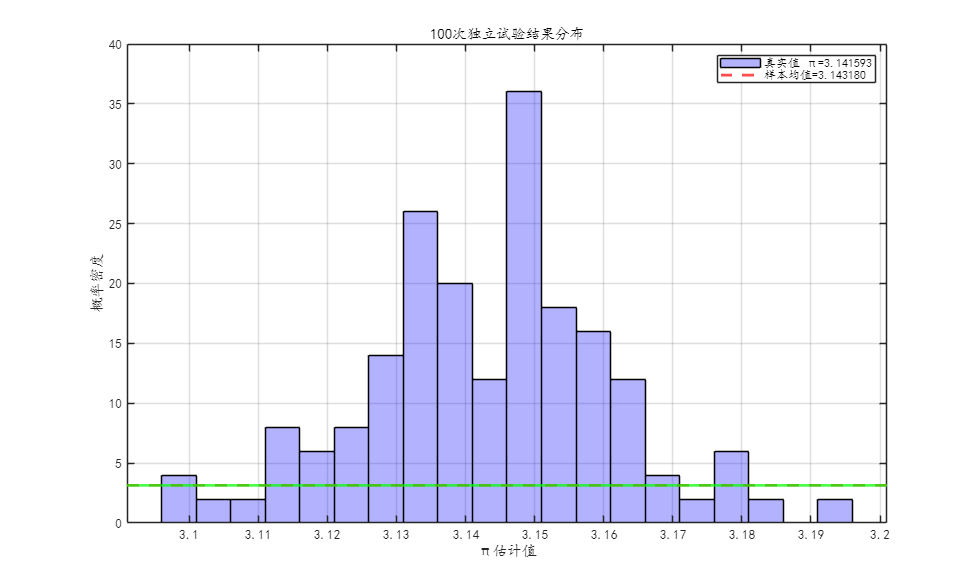


% 绘制直方图
figure('Position', [100, 100, 1000, 600]);
histogram(trial_results, 20, 'Normalization', 'pdf', 'FaceAlpha', 0.7, ...
    'FaceColor', 'blue', 'EdgeColor', 'black');
hold on;
yline(pi, 'r--', 'LineWidth', 2);
yline(mean(trial_results), 'g-', 'LineWidth', 2);
xlabel('π估计值');
ylabel('概率密度');
title(sprintf('%d次独立试验结果分布', n_trials));
legend(sprintf('真实值 π=%.6f', pi), sprintf('样本均值=%.6f', mean(trial_results)));
grid on;
alpha(0.3);

%% ============================================================================
%% 练习二：复杂函数的定积分计算
%% Exercise 2: Complex Function Integration
%% ============================================================================

fprintf("====================================");

fprintf("\n练习二：复杂函数的蒙特卡洛积分\n");


练习二：复杂函数的蒙特卡洛积分


fprintf("Exercise 2: Monte Carlo Integration of Complex Functions\n");

Exercise 2: Monte Carlo Integration of Complex Functions


fprintf("====================================");

fprintf("\n");

function y = target_function(x)
    % 目标函数: f(x) = e^(-x²) * sin(x)
    y = exp(-x.^2) .* sin(x);
end

function [integral, std_error, samples, func_values] = monte_carlo_integral(func, a, b, n)
    % 蒙特卡洛积分计算
    % 参数:
    %   func: 被积函数
    %   a, b: 积分下限和上限
    %   n: 随机样本数量
    % 返回:
    %   integral: 积分估计值
    %   std_error: 标准误差
    %   samples: 样本点
    %   func_values: 函数值
    
    % 生成随机样本
    samples = a + (b - a) * rand(1, n);
    
    % 计算函数值
    func_values = func(samples);
    
    % 蒙特卡洛积分估计
    integral = (b - a) * mean(func_values);
    
    % 标准误差估计
    std_error = (b - a) * std(func_values) / sqrt(n);
end

%% 2.1 函数可视化
fprintf("\n2.1 目标函数可视化\n");


2.1 目标函数可视化


x_plot = linspace(0, 2, 1000);
y_plot = target_function(x_plot);

figure('Position', [100, 100, 1200, 800]);

% 子图1：函数图像
subplot(2, 2, 1);
plot(x_plot, y_plot, 'b-', 'LineWidth', 2);
hold on;
fill([x_plot, fliplr(x_plot)], [y_plot, zeros(1, length(x_plot))], 'blue', ...
    'FaceAlpha', 0.3, 'EdgeColor', 'none');
xlabel('x');
ylabel('f(x)');
title('目标函数');
legend('f(x) = e^{-x²}sin(x)');
grid on;
alpha(0.3);

% 子图2：函数组成部分
subplot(2, 2, 2);
plot(x_plot, exp(-x_plot.^2), 'r-', 'LineWidth', 2);
hold on;
plot(x_plot, sin(x_plot), 'g-', 'LineWidth', 2);
plot(x_plot, y_plot, 'b-', 'LineWidth', 2);
xlabel('x');
ylabel('y');
title('函数组成部分');
legend('e^{-x²}', 'sin(x)', 'e^{-x²}sin(x)');
grid on;
alpha(0.3);

%% 2.2 单次积分计算
fprintf("\n2.2 单次蒙特卡洛积分计算\n");


2.2 单次蒙特卡洛积分计算


a = 0; b = 2;  % 积分区间
n_samples = 100000;

[integral_mc, error_mc, samples, func_vals] = monte_carlo_integral(@target_function, a, b, n_samples);

% 使用MATLAB的integral函数作为参考
integral_scipy = integral(@target_function, a, b);
fprintf("积分区间: [%d, %d]\n", a, b);

积分区间: [0, 2]


fprintf("样本数量: %d\n", n_samples);

样本数量: 100000


fprintf("蒙特卡洛估计: %.6f ± %.6f\n", integral_mc, error_mc);

蒙特卡洛估计: 0.421850 ± 0.000832


fprintf("MATLAB数值积分: %.6f\n", integral_scipy);

MATLAB数值积分: 0.421164


fprintf("绝对误差: %.6f\n", abs(integral_mc - integral_scipy));

绝对误差: 0.000685


fprintf("相对误差: %.3f%%\n", abs(integral_mc - integral_scipy)/abs(integral_scipy)*100);

相对误差: 0.163%


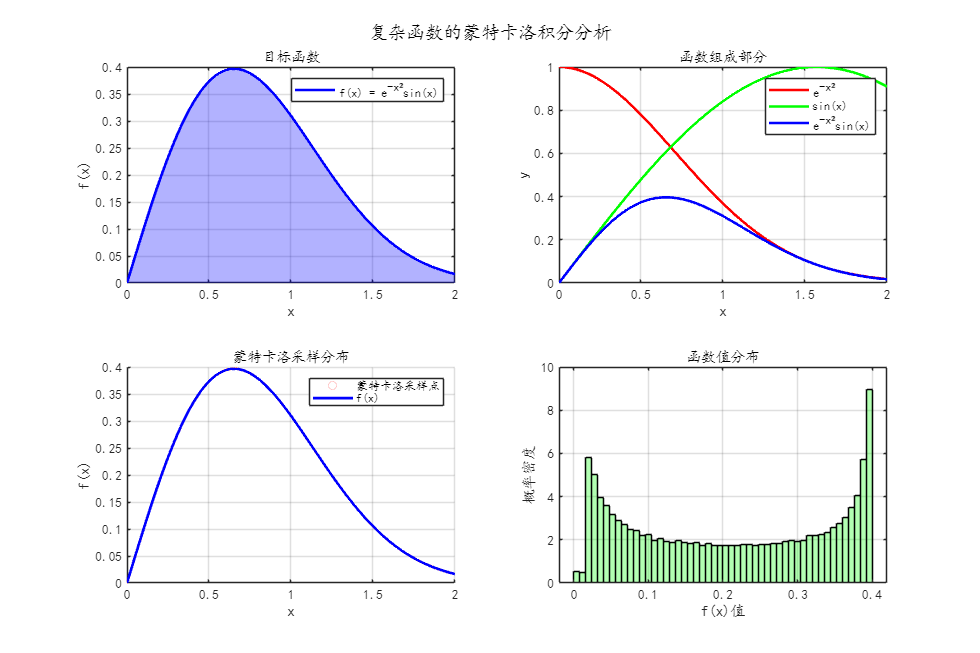


% 子图3：蒙特卡洛采样点
subplot(2, 2, 3);
sample_subset = samples(1:1000);  % 只显示部分采样点
func_subset = func_vals(1:1000);
scatter(sample_subset, func_subset, 1, 'r', 'MarkerEdgeAlpha', 0.6);
hold on;
plot(x_plot, y_plot, 'b-', 'LineWidth', 2);
xlabel('x');
ylabel('f(x)');
title('蒙特卡洛采样分布');
legend('蒙特卡洛采样点', 'f(x)');
grid on;
alpha(0.3);

% 子图4：函数值分布
subplot(2, 2, 4);
histogram(func_vals, 50, 'Normalization', 'pdf', 'FaceAlpha', 0.7, ...
    'FaceColor', 'green', 'EdgeColor', 'black');
xlabel('f(x)值');
ylabel('概率密度');
title('函数值分布');
grid on;
alpha(0.3);

sgtitle('复杂函数的蒙特卡洛积分分析');


%% 2.3 收敛性分析
fprintf("\n2.3 积分收敛性分析\n");


2.3 积分收敛性分析


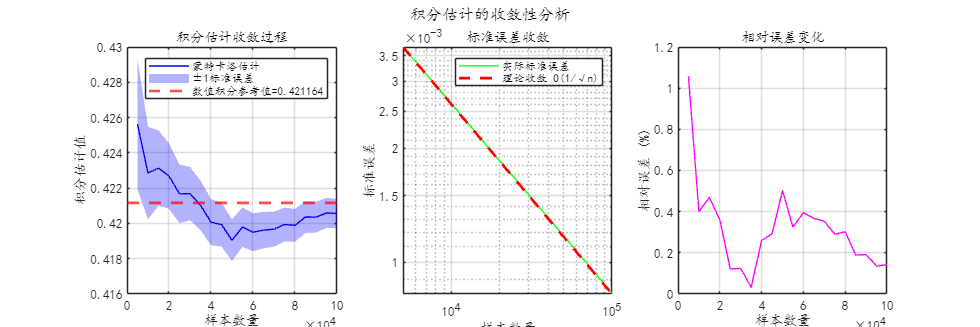


function [n_values, integrals, errors] = integral_convergence_analysis(func, a, b, max_n, step)
    % 分析积分估计的收敛过程
    n_values = step:step:max_n;
    integrals = zeros(1, length(n_values));
    errors = zeros(1, length(n_values));
    
    % 一次性生成所有随机数
    all_samples = a + (b - a) * rand(1, max_n);
    all_func_values = func(all_samples);
    
    for i = 1:length(n_values)
        n = n_values(i);
        % 使用前n个样本
        current_samples = all_func_values(1:n);
        integral_est = (b - a) * mean(current_samples);
        std_err = (b - a) * std(current_samples) / sqrt(n);
        
        integrals(i) = integral_est;
        errors(i) = std_err;
    end
end

[n_vals_int, integrals_int, errors_int] = integral_convergence_analysis(@target_function, a, b, 100000, 5000);

% 绘制收敛过程
figure('Position', [100, 100, 1500, 500]);

% 积分值收敛
subplot(1, 3, 1);
plot(n_vals_int, integrals_int, 'b-', 'LineWidth', 1);
hold on;
yline(integral_scipy, 'r--', 'LineWidth', 2);
fill([n_vals_int, fliplr(n_vals_int)], ...
    [integrals_int - errors_int, fliplr(integrals_int + errors_int)], ...
    'blue', 'FaceAlpha', 0.3, 'EdgeColor', 'none');
xlabel('样本数量');
ylabel('积分估计值');
title('积分估计收敛过程');
legend('蒙特卡洛估计', sprintf('数值积分参考值=%.6f', integral_scipy), '±1标准误差');
grid on;
alpha(0.3);

% 标准误差变化
subplot(1, 3, 2);
plot(n_vals_int, errors_int, 'g-', 'LineWidth', 1);
hold on;
plot(n_vals_int, errors_int(1)*sqrt(n_vals_int(1))./sqrt(n_vals_int), ...
    'r--', 'LineWidth', 2);
xlabel('样本数量');
ylabel('标准误差');
title('标准误差收敛');
legend('实际标准误差', '理论收敛 O(1/√n)');
grid on;
alpha(0.3);
set(gca, 'YScale', 'log');
set(gca, 'XScale', 'log');

% 相对误差
subplot(1, 3, 3);
rel_errors = abs(integrals_int - integral_scipy)./abs(integral_scipy)*100;
plot(n_vals_int, rel_errors, 'm-', 'LineWidth', 1);
xlabel('样本数量');
ylabel('相对误差 (%)');
title('相对误差变化');
grid on;
alpha(0.3);

sgtitle('积分估计的收敛性分析');


%% 2.4 不同积分方法比较
fprintf("\n2.4 不同数值积分方法比较\n");


2.4 不同数值积分方法比较



% 比较不同样本量下的计算时间和精度
sample_sizes = [1000, 5000, 10000, 50000, 100000];
results_comparison = table();

for i = 1:length(sample_sizes)
    n = sample_sizes(i);
    
    % 蒙特卡洛方法
    start_time = tic;
    [mc_result, mc_error, ~, ~] = monte_carlo_integral(@target_function, a, b, n);
    mc_time = toc(start_time);
    
    % 计算与参考值的误差
    mc_abs_error = abs(mc_result - integral_scipy);
    
    % 存储结果
    results_comparison(i, :) = table(n, mc_result, mc_error, mc_abs_error, ...
        mc_abs_error/abs(integral_scipy)*100, mc_time, ...
        'VariableNames', {'样本数', '蒙特卡洛估计', '标准误差', '绝对误差', '相对误差百分比', '计算时间秒'});
end

% 显示结果
disp("不同样本量的计算结果比较:");

不同样本量的计算结果比较:


disp(results_comparison);

    样本数    蒙特卡洛估计     标准误差       绝对误差      相对误差百分比    计算时间秒
    _____    __________    __________    __________    ____________    _________
     1000     0.41781       0.0084199     0.0033528       0.79608      0.0002583
     5000     0.42611       0.0036905      0.004946        1.1744      0.0003054
    10000     0.42194       0.0026282    0.00078074       0.18538      0.0003176
    50000     0.41916       0.0011767     0.0020015       0.47522      0.0011442
    1e+05     0.42101      0.00083238     0.0001563      0.037111      0.0015567


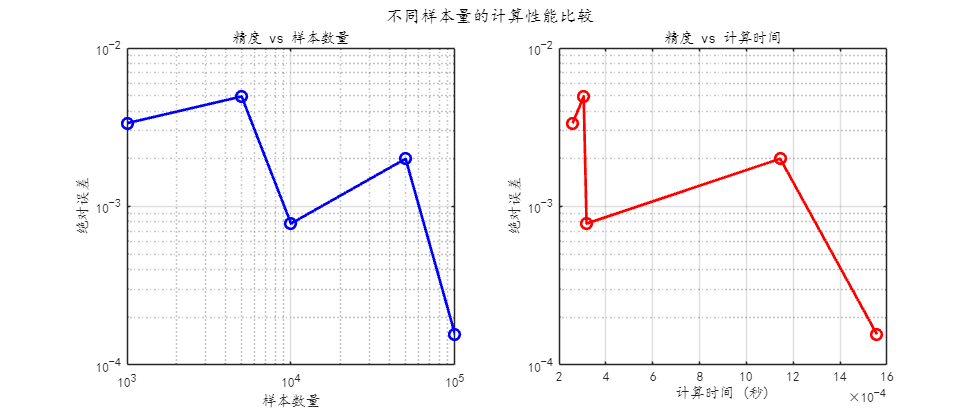


% 绘制精度vs计算时间
figure('Position', [100, 100, 1200, 500]);

subplot(1, 2, 1);
loglog(results_comparison.("样本数"), results_comparison.("绝对误差"), 'bo-', 'LineWidth', 2, 'MarkerSize', 8);
xlabel('样本数量');
ylabel('绝对误差');
title('精度 vs 样本数量');
grid on;
alpha(0.3);

subplot(1, 2, 2);
plot(results_comparison.("计算时间秒"), results_comparison.("绝对误差"), 'ro-', 'LineWidth', 2, 'MarkerSize', 8);
xlabel('计算时间 (秒)');
ylabel('绝对误差');
title('精度 vs 计算时间');
grid on;
alpha(0.3);
set(gca, 'YScale', 'log');

sgtitle('不同样本量的计算性能比较');


%% 2.5 置信区间分析
fprintf("\n2.5 置信区间分析\n");


2.5 置信区间分析



function [results, coverage_rate, reference_value] = confidence_interval_analysis(func, a, b, n, confidence_level, n_trials)
    % 进行多次独立试验，分析置信区间的覆盖率
    % 参数:
    %   func: 被积函数
    %   a, b: 积分区间
    %   n: 每次试验的样本数
    %   confidence_level: 置信水平
    %   n_trials: 试验次数
    
    % 参考值
    reference_value = integral(func, a, b);
    
    % 计算置信区间的z值
    alpha = 1 - confidence_level;
    z_value = norminv(1 - alpha/2);
    
    results = struct('test', [], 'estimate', [], 'lower', [], 'upper', [], 'width', [], 'cover', []);
    coverage_count = 0;
    
    for trial = 1:n_trials
        % 进行蒙特卡洛积分
        [integral_est, std_error, ~, ~] = monte_carlo_integral(func, a, b, n);
        
        % 计算置信区间
        lower_bound = integral_est - z_value * std_error;
        upper_bound = integral_est + z_value * std_error;
        
        % 检查是否覆盖真值
        covers_true_value = (lower_bound <= reference_value) && (reference_value <= upper_bound);
        if covers_true_value
            coverage_count = coverage_count + 1;
        end
        
        % 存储结果
        results(trial).("test") = trial;
        results(trial).("estimate") = integral_est;
        results(trial).("lower") = lower_bound;
        results(trial).("upper") = upper_bound;
        results(trial).("width") = upper_bound - lower_bound;
        results(trial).("cover") = covers_true_value;
    end
    
    coverage_rate = coverage_count / n_trials;
end

[ci_results, coverage_rate, ref_val] = confidence_interval_analysis(...
    @target_function, a, b, 10000, 0.95, 50);

fprintf("95%%置信区间分析结果 (基于%d次独立试验):\n", length(ci_results));

95%置信区间分析结果 (基于50次独立试验):


fprintf("理论覆盖率: 95%%\n");

理论覆盖率: 95%


fprintf("实际覆盖率: %.1f%%\n", coverage_rate*100);

实际覆盖率: 94.0%


fprintf("参考积分值: %.6f\n", ref_val);

参考积分值: 0.421164


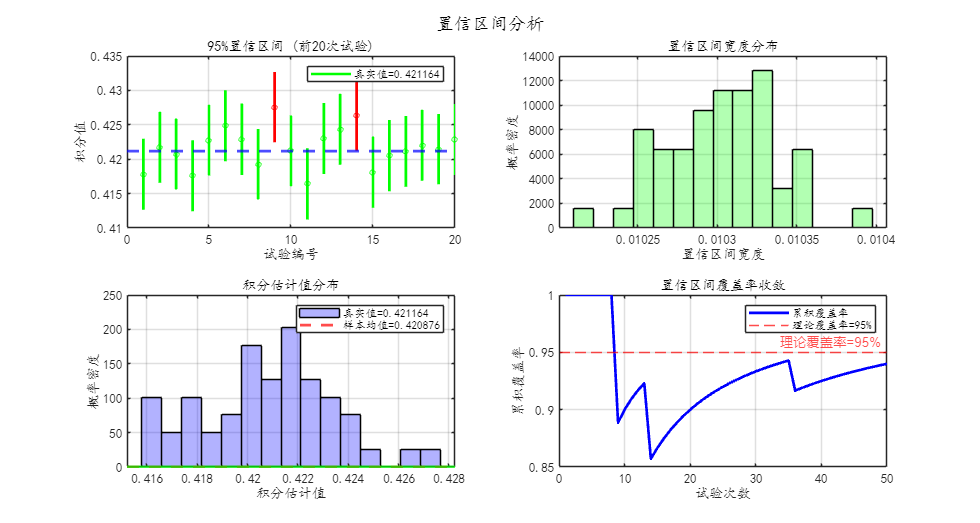


% 可视化置信区间
figure('Position', [100, 100, 1500, 800]);

% 子图1：置信区间可视化
subplot(2, 2, 1);
trial_nums = 1:20;  % 只显示前20个
for i = trial_nums
    est = ci_results(i).("estimate");
    lower = ci_results(i).("upper");
    upper = ci_results(i).("lower");
    cover = ci_results(i).("cover");
    
    color = 'green';
    if ~cover
        color = 'red';
    end
    
    plot([i, i], [lower, upper], 'Color', color, 'LineWidth', 2);
    hold on;
    plot(i, est, 'o', 'Color', color, 'MarkerSize', 4);
end

yline(ref_val, 'b--', 'LineWidth', 2);
xlabel('试验编号');
ylabel('积分值');
title('95%置信区间 (前20次试验)');
legend(sprintf('真实值=%.6f', ref_val));
grid on;
alpha(0.3);

% 子图2：区间宽度分布
subplot(2, 2, 2);
widths = [ci_results.("width")];
histogram(widths, 15, 'Normalization', 'pdf', 'FaceAlpha', 0.7, ...
    'FaceColor', 'green', 'EdgeColor', 'black');
xlabel('置信区间宽度');
ylabel('概率密度');
title('置信区间宽度分布');
grid on;
alpha(0.3);

% 子图3：估计值分布
subplot(2, 2, 3);
all_estimates = [ci_results.("estimate")];
histogram(all_estimates, 15, 'Normalization', 'pdf', 'FaceAlpha', 0.7, ...
    'FaceColor', 'blue', 'EdgeColor', 'black');
hold on;
yline(ref_val, 'r--', 'LineWidth', 2);
yline(mean(all_estimates), 'g-', 'LineWidth', 2);
xlabel('积分估计值');
ylabel('概率密度');
title('积分估计值分布');
legend(sprintf('真实值=%.6f', ref_val), sprintf('样本均值=%.6f', mean(all_estimates)));
grid on;
alpha(0.3);

% 子图4：覆盖率随试验次数变化
subplot(2, 2, 4);
cumulative_coverage = zeros(1, length(ci_results));
cumulative_count = 0;
for i = 1:length(ci_results)
    if ci_results(i).("cover")
        cumulative_count = cumulative_count + 1;
    end
    cumulative_coverage(i) = cumulative_count / i;
end

plot(1:length(ci_results), cumulative_coverage, 'b-', 'LineWidth', 2);
hold on;
yline(0.95, 'r--', '理论覆盖率=95%');
xlabel('试验次数');
ylabel('累积覆盖率');
title('置信区间覆盖率收敛');
legend('累积覆盖率', '理论覆盖率=95%');
grid on;
alpha(0.3);

sgtitle('置信区间分析');